## Welcome to Warp Factory!

In this example, we'll learn the basics of metrics.

### First metric

gridSize = [1 10 10 10];
gridScaling = [1 1 1 1];
MyFirstMetric = metricGet_Minkowski(gridSize, gridScaling);

Check out the properties of the metric struct

fieldnames(MyFirstMetric)

ans = 7×1 cell array
    {'type'   }
    {'name'   }
    {'scaling'}
    {'coords' }
    {'index'  }
    {'date'   }
    {'tensor' }


### MyFirstMetric.type

This one is simple. The .type property of this tensor is "metric". This identifies this tensor object as a metric.

MyFirstMetric.type

ans = "metric"

### MyFirstMetric.index

This property specifies what form the tensor is in. A metric tensor index can either be "covariant" ($g_{\mu\nu}$) or "contravariant" ($g^{\mu\nu}$).

MyFirstMetric.index

ans = "covariant"

### MyFirstMetric.tensor

The tensor contains the values for metric at each point in space and time for each tensor component. The tensor object is a 4x4 cell array. Each cell contains an array of values for each point in spacetime. The size of this array is equal to the gridSize of your spacetime.

MyFirstMetric.tensor

ans = 4×4 cell array
    {1×10×10×10 double}    {1×10×10×10 double}    {1×10×10×10 double}    {1×10×10×10 double}
    {1×10×10×10 double}    {1×10×10×10 double}    {1×10×10×10 double}    {1×10×10×10 double}
    {1×10×10×10 double}    {1×10×10×10 double}    {1×10×10×10 double}    {1×10×10×10 double}
    {1×10×10×10 double}    {1×10×10×10 double}    {1×10×10×10 double}    {1×10×10×10 double}


Let's take a look at the tensor values for a slice of the space.

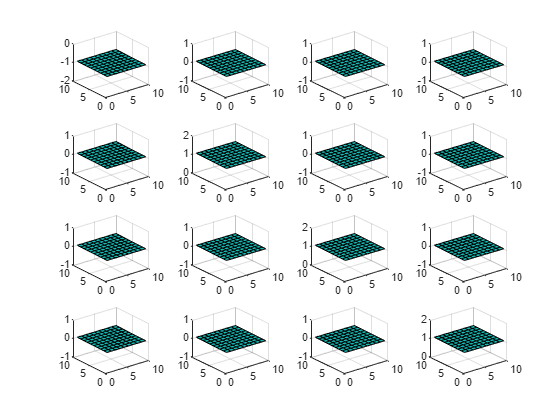

for i = 1:4
    for j = 1:4
        nexttile
        surfq(MyFirstMetric.tensor{i,j}(1,:,:,1))
    end
end

Just as expected for Minkowski space! ($g_{\mu\nu} = \eta_{\mu\nu}$ for all points in the slice)

### Other Properties

.name - Your metric has a name!

.date - Your metric stores a date when it is made.

.scaling - Your metric has scaling information about the coordinate grid step size in time and space. We'll get into this more in later examples.

.coords - The coordinate system associated with the metric. 'cartesian'

MyFirstMetric.name

ans = "Minkowski"

MyFirstMetric.date

ans = '12-Jun-2023'

MyFirstMetric.scaling

ans =      1     1     1     1


MyFirstMetric.coords

ans = "cartesian"